2024/4/26      Digital Image Processing midterm

Name: 涂价弘                       Student ID: 109321019

Write your code in the code area below the question. Add comments to important lines. Rename the .mlx as **midterm_yourID.mlx**. Submit both your** .mlx** and** .pdf** to the moodle.

*** **Don't try to google codes or use ChatGPT.** If you cheat, you will get 0  in the midterm examination.

**1. Image Quantization (15%)**

Quantization refers to the number of grayscales used to represent the image. For example, **uniform quantization** of 4 grayscales, maps the input grayscale to the output values as follows:

Original values                Output value

0~63                                0

64~127                            1

128~191                          2

192~255                          3

**a) **Use simple arithemetic operations (+,-,*,/,floor, ceil,...) to perform image quatization to the** newborn.tif. Quantize to 32 grayscales and 4 grayscales. Show the quantized images. (8%)**

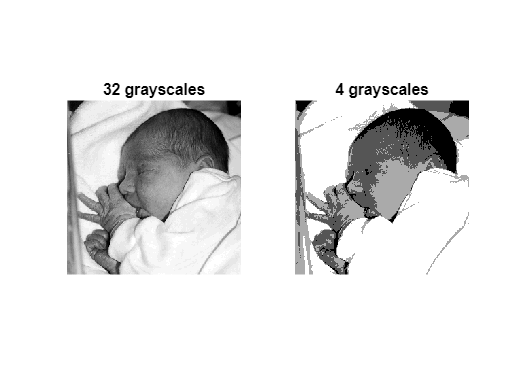

clf('reset')
I = imread("./images/newborn.tif");

I32 = uint8(floor(double(I) / 8));
I4 = uint8(floor(double(I) / 64));

subplot(1, 2, 1)
imshow(I32, [])
title('32 grayscales')
subplot(1, 2, 2)
imshow(I4, [])
title('4 grayscales')

**b)** Perform the same operations in a) by using Matlab buld-in function **imquantize**. Read the document about how to use it.** (7%)**

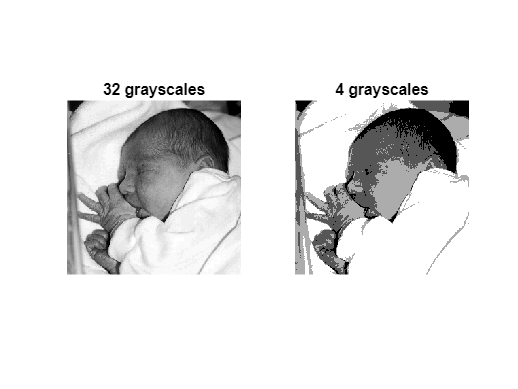

clf('reset')
I = imread("./images/newborn.tif");

thresh_32 = zeros(1, 31);
thresh_32(1) = 8;

for i = 2:31
    thresh_32(i) = thresh_32(i - 1) + 8;
end

thresh_4 = zeros(1, 3);
thresh_4(1) = 64;

for i = 2:3
    thresh_4(i) = thresh_4(i - 1) + 64;
end

valuesMax = [thresh_32 max(I(:))];
quant32_I = imquantize(I, thresh_32, valuesMax);

valuesMax = [thresh_4 max(I(:))];
quant4_I = imquantize(I, thresh_4, valuesMax);

subplot(1, 2, 1)
imshow(quant32_I, [])
title('32 grayscales')
subplot(1, 2, 2)
imshow(quant4_I, [])
title('4 grayscales')

**2. Simple Convolutional Neural Network (CNN) (40%)**

**convolution stage: (10%)**

For the cameraman.tif image, apply both the** horizontal and vertical Sobel** filters to it and show the filtered results. Use 'same' option.

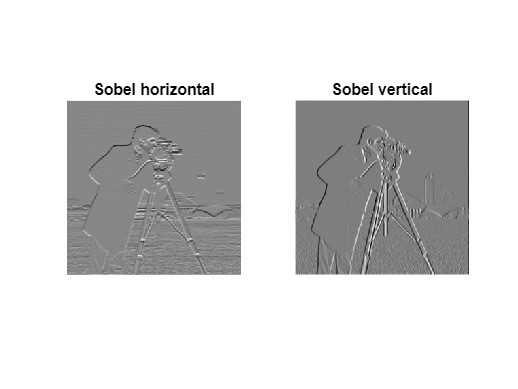

clf('reset')

f1 = ones(3, 3) / 9;
f2 = ones(5, 5) / 25;

I = imread('./images/cameraman.tif');
Sobel_x = [-1 -2 -1; 0 0 0; 1 2 1];

icx = filter2(Sobel_x, I, 'same');
subplot(1, 2, 1)
imshow(icx, [])
title('Sobel horizontal')

Sobel_y = Sobel_x';

icy = filter2(Sobel_y, I, 'same');
subplot(1, 2, 2)
imshow(icy, []);
title('Sobel vertical')

**max-pooling stage: (15%)**

For each **2x2 non-overlapping block **in the convolved image, take the maximum value among the 4 pixels. Then wirte the maximum pixel value into a output image. So the output image has 1/2 size in both the width and height. Apply the max-pooling to both the vertical and horizontal Sobel filtered images and show the results.

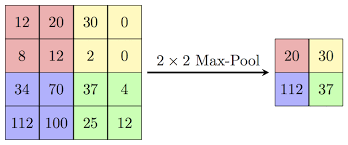

(*** **Do not use any built-in Matlab function (ex. imresize)** for image resize or down-sampling. Use **for loop**  or **basic Matlab matrix operation ** for your code.)

max-pooling for Sobel filtered image of horizontal edges:

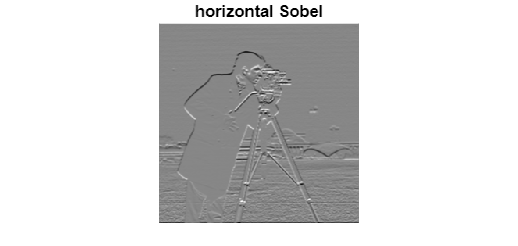

clf('reset')

max_pooling_I = zeros(256 / 2, 256 / 2);

for i = 2:2:size(icx, 1)
    for j = 2:2:size(I, 2)
        max_pooling_I(i/2, j/2) = max(max(icx(i-1:i, j-1:j)));
    end
end

imshow(icx, [])
title('horizontal Sobel')
truesize([400 800])

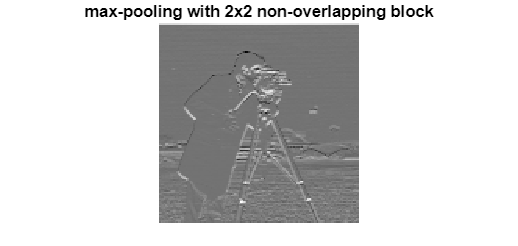

imshow(max_pooling_I, [])
title('max-pooling with 2x2 non-overlapping block')
truesize([400 800])

**Relu stage: (15%)**

Apply the Relu operation to the output images in the max-pooling stage. Then show the results.

Relu operation:

if  I(x,y) > 0 then I(x,y)=I(x,y)

else I(x,y) = 0;

(*** **Do not use any built-in Matlab function for Relu**. Use **for loop** or **basic matrix operation** for your code.)

Relu for the vertical maxpooling image:

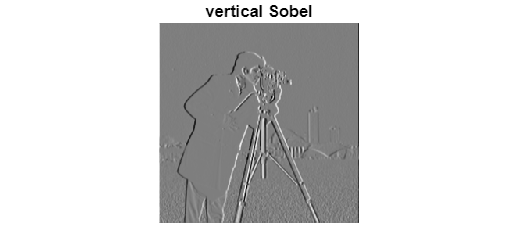

clf('reset')

max_pooling_I = zeros(256 / 2, 256 / 2);

for i = 2:2:size(icy, 1)
    for j = 2:2:size(I, 2)
        max_pooling_I(i/2, j/2) = max(max(icy(i-1:i, j-1:j)));
    end
end

relu_I = zeros(256 / 2, 256 / 2);

for i = 1:size(max_pooling_I, 1)
    for j = 1:size(max_pooling_I, 2)
        if (max_pooling_I(i, j) <= 0)
            max_pooling_I(i, j) = 0;
        end
    end
end

imshow(icy, [])
title('vertical Sobel')
truesize([400 800])

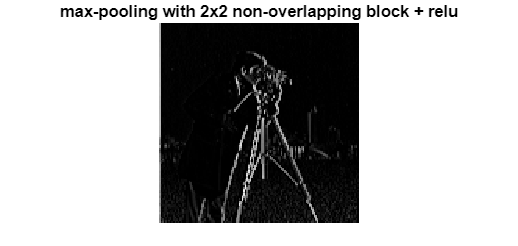

imshow(max_pooling_I, [])
title('max-pooling with 2x2 non-overlapping block + relu')
truesize([400 800])

**3. Image arithmetics (10%)**

Create a look-up table (LUT) to perform image negative. Plot the look-up table.(5%)

LUT = (0:255) * -1

LUT =      0    -1    -2    -3    -4    -5    -6    -7    -8    -9   -10   -11   -12   -13   -14   -15   -16   -17   -18   -19   -20   -21   -22   -23   -24   -25   -26   -27   -28   -29   -30   -31   -32   -33   -34   -35   -36   -37   -38   -39   -40   -41   -42   -43   -44   -45   -46   -47   -48   -49


Apply image negative to the **newborn.tif and show the result**. (5%)

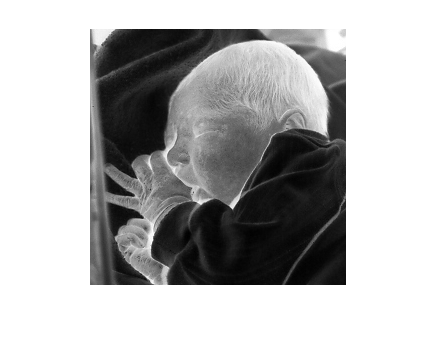

clf("reset")
I = imread('./images/newborn.tif');
imshow(LUT(I + 1), [])

**4. Histogram (15%)**

a) The following code  will show a darker version of the cameraman image.  Explain why? (5%)

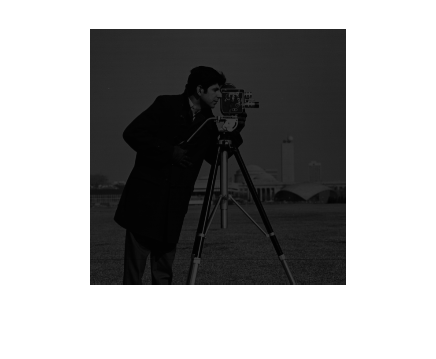

clf('reset')

c=imread('./images/cameraman.tif');
[x, map]=gray2ind(c);
imshow(x)

Ans: 因為較大的 pixel 值被轉成較小的 pixel 值，colormap 集中在較暗的區間，加上顯示圖片時沒有重新指定 colormap 造成亮度較暗。

b) Show the histogram of the original cameraman image and variable x **using Matlab build-in function imhist**. Beware to adjust the margin of the histogram. After observing the histogram, you might get some hints on a). (5%)

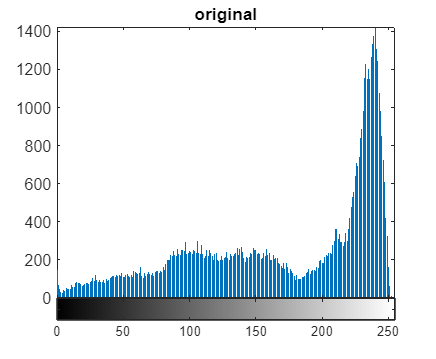

imhist(I), axis tight
title('original')

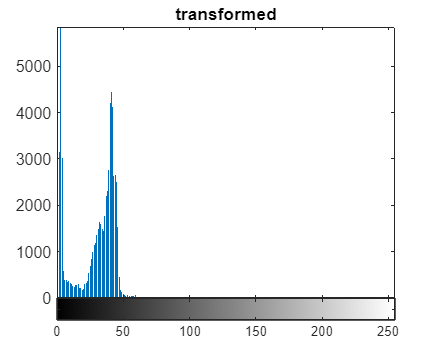

imhist(x), axis tight
title('transformed')

c) Apply **histogram equalization** to x using Matlab build-in function **histeq**. Show the equalization function and the transformed image. (5%)

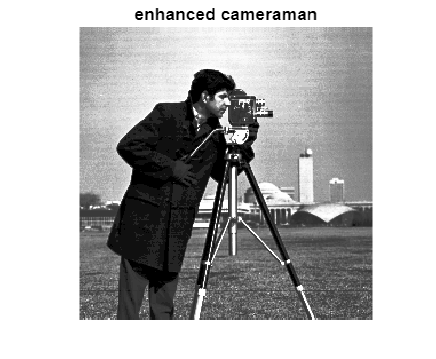

[J, T] = histeq(x);
imshow(J, [])
title("enhanced cameraman")

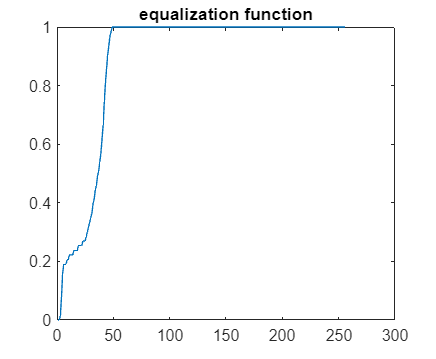


plot(T)
title('equalization function')

**5. Thresholding and Morphology (20%)**

Read the Matlab build-in image coins.png.

clf('reset')

I = imread("coins.png");

a) Show the histogram of I, and apply appropriate threshold to separate the foreground (coins) and background. Show the binary image after thresholding. (10%)

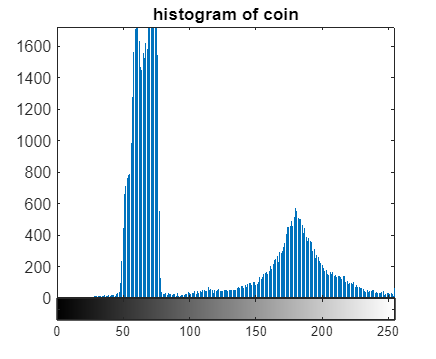

imhist(I)
title('histogram of coin')

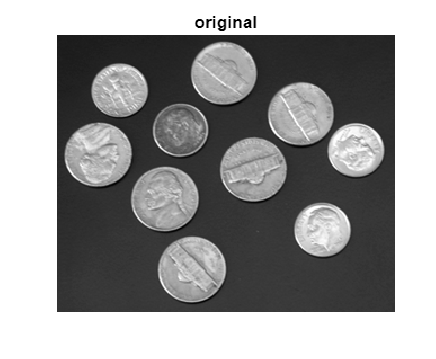


imshow(I, [])
title('original')

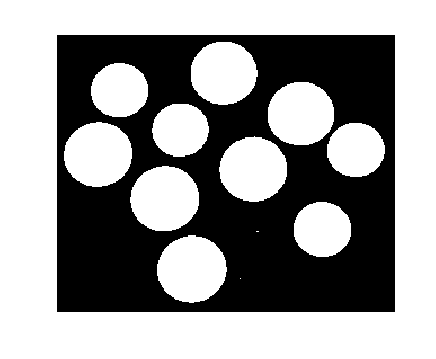


thresholding_I = I > 80;
imshow(thresholding_I)

b) 

Apply appropriate morphological operations to **remove noises** and **fill the holes**. Show the intermediate images and explain what you get after each operation.(10%)

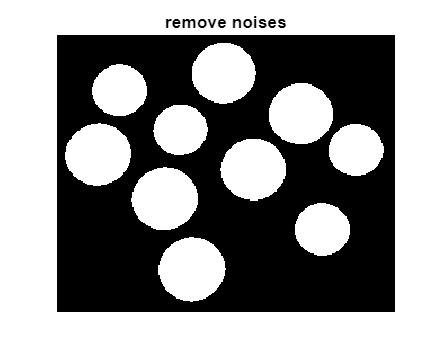

% 準備 3x3 大小的 filter kernel
sq = ones(3, 3);

% 用侵蝕的方法去除雜訊
erode = imerode(thresholding_I, sq);
imshow(erode, [])
title('remove noises')

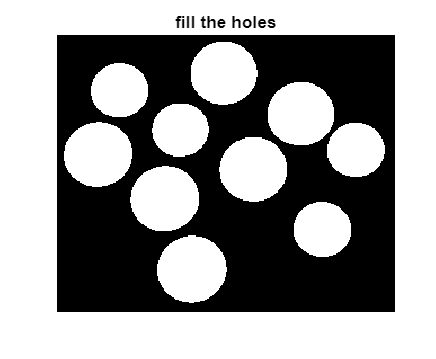


% 用擴張的方法填補剛剛侵蝕造成的漏洞
dilate = imdilate(erode, sq);
imshow(dilate, [])
title('fill the holes')